# 23 Principal Components Analyses

## 23.1 Purpose and Interpretations of Principal Components Analysis

The EEG data from one time point can be conceptualized as a location in a high-dimensional space, with each dimension corresponding to each timepoint (or, for purposes of this chapter, each dimension corresponds to each electrode). In this framework, EEG data over time can be conceptualized as a line traveling through this high-dimensional space. This conceptualization is useful for principal components analysis (PCA).

The goal of PCA is to construct sets of weights (called principal components) based on the covariance of a set of correlated variables (here, electrodes) so that components explain all of the variance of the data such that the components: 

- Are uncorrelated with each other.

- Are created so that the first principal component explains as much variance as possible for one variable, the second principal component explains as much of the residual variance as possible for one variable while being orthogonal to the first component, and so on, for as many components as there are electrodes (variables).

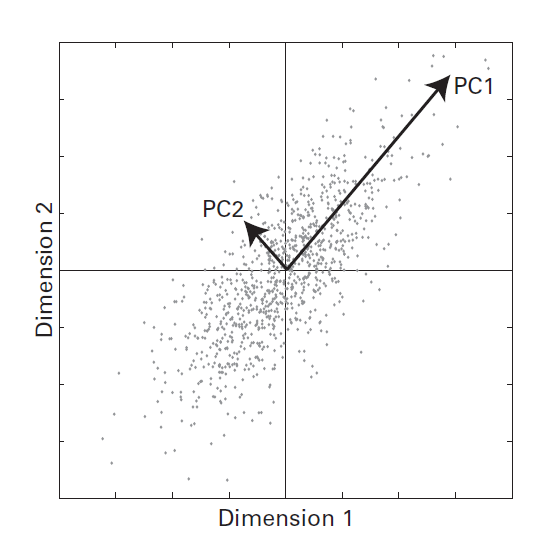

**Figure 23.1**

*Conceptual illustration of PCA.*

There are several ways to interpret the result of a PCA on EEG data: 

- Each principal component is a vector in a n-dimensional space (one dimension for each electrode) that characterizes the "direction" of the data distribution (geometric interpretation). 

- PCA can be used to create a set of spatial filters in which the weights for each electrode are defined by patterns of interelectrode temporal covariance.

- PCA can also be interpreted as a dimensional reduction technique.

The PCA and the surface Laplacian can be conceptualized as spatial filters that provide information about opposite sides of the spatial spectrum: 

- Surface Laplacian computes weights based on interelectrode distances and explicitly attenuates low-spatial-frequency activity and therefore highlights local features of the data.

- PCA computes weights based on statistical properties of the data and highlights global spatial features of the data by identifying patterns of large-scale covariance. Local topographical features contribute relatively little to the covariance matrix and are thus less likely to contribute to the first few principal components that are typically analyzed.

PCA can be computed over any set of variables and observations.

## 23.2 How PCA Is Computed

The first step of computing a PCA is to construct a covariance matrix. A covariance matrix is like a correlation matrix, but it retains the scale of the data. It can be obtained using matrix algebra by subtracting the mean and multiplying the data (electrodes x time points) by its transpose.

### 
$$\textrm{covariance}=(n-1)^{-1} (X-\bar{X} )(X-\bar{X} )^T$$


- $X$ is an electrodes-by-time-points matrix

- $\bar{X}$ is the mean signal of each electrode over time

- $n$ is the number of instances, or time points

If your data are time-by-electrodes, you would need to transpose the first matrix, not the second matrix (or transpose the data to be electrodes by time).  Subtracting the mean before computing the covariance is necessary for the PCA to follow patterns of variance; otherwise, the first component will reflect the mean signal. Because this is a covariance matrix, the diagonals will contain the variances of each electrode. Dividing by n - 1 is a normalization factor. n - 1 should be used when sampling from a population.

The covariance matrix can be computed from: 

- The ERP. 

- All time points from all trials, concatenated into a large 2-D matrix.

- Each trial, and then the covariance matrices from each trial can be averaged together. 

The third approach is advantageous because it increases the signal-to-noise ratio of the covariance matrix. Although the latter two methods generally produce similar results, there is a distinction between the first and the latter two covariance matrices: the covariance of the ERP can be conceptualized as reflecting the phase-locked (evoked) covariance, whereas the covariance of the single-trial EEG data can be conceptualized as reflecting the total (phase-locked and non-phase-locked) covariance.

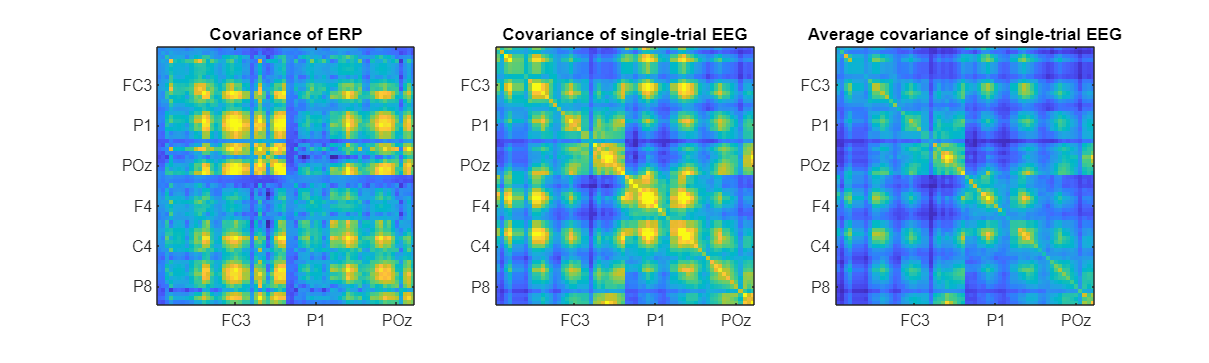

load sampleEEGdata

erp = squeeze(mean(EEG.data,3));

erp = bsxfun(@minus,erp,mean(erp,2));
covar = (erp*erp')./(EEG.pnts-1);

figure(Position=[100,100,1000,300])

subplot(131)
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[-1 5])
title('Covariance of ERP')

subplot(132)
eeg = reshape(EEG.data,EEG.nbchan,EEG.pnts*EEG.trials);
eeg = bsxfun(@minus,eeg,mean(eeg,2));
covar = (eeg*eeg')./(length(eeg)-1);
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[20 150])
title('Covariance of single-trial EEG')

subplot(133)
covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[20 150])
title('Average covariance of single-trial EEG')

**Figure 23.2**

*Matrices showing covariance (units are µV) among all pairs of electrodes computed in slightly different ways.*

Once a covariance matrix is computed, the next step is to perform an eigendecomposition via the Matlab function `eig`. An eigendecomposition is a matrix decomposition that returns eigenvectors and their associated eigenvalues, which characterize the patterns of interelectrode covariance. Thinking back to figure 23.1, the eigenvectors are the new rotated axes, and the eigenvalues are the lengths of those axes. In the parlance of PCA the eigenvectors are the principal components or the weights for each electrode that, when applied to the electrode time series, produce the PCA time courses. The eigenvalues can be scaled to percentage variance accounted for by dividing each eigenvalue by the sum of all eigenvalues and multiplying by 100.

Note that the Matlab function eig returns eigenvalues and eigenvectors in ascending order; you might find it more intuitive to have the components sorted in descending order (thus, the biggest component is the first rather than the last).

The results of the eigenvalue decomposition are square matrices with as many rows/columns as there are variables (electrodes). Each column in the eigenvector matrix is a principal component, and each row stores the weights (also called component loadings) of each electrode. 

The electrode weights for each component can be plotted as topographical maps, and time courses of the components can be obtained by multiplying the weights by the electrode time series data. Note that this means that each component has one associated time course, and that time course is a weighted sum of the activity of all electrodes.

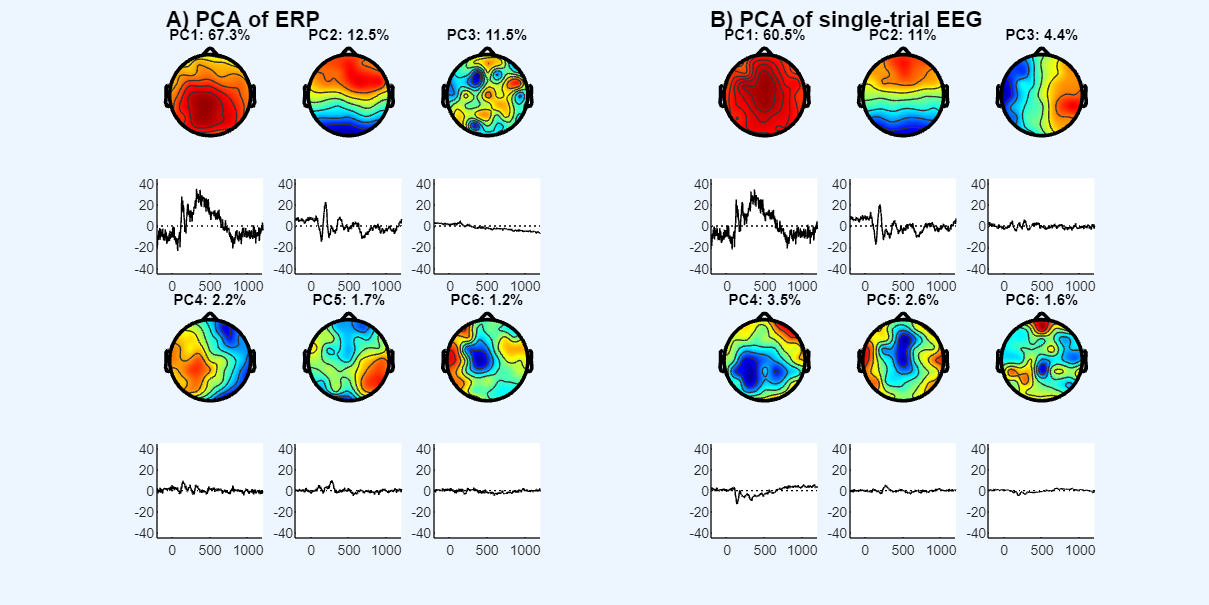

figure('Position',[100 100 1400 700])
idx = [1 2 3 15 16 17];

erp = squeeze(mean(EEG.data,3));
erp = bsxfun(@minus,erp,mean(erp,2));
covar = (erp*erp')./(EEG.pnts-1);

[pc,eigvals] = eig(covar);

pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals);

for i=1:6
    subplot(4,7,idx(i))
    topoplot(double(pc(:,i)),EEG.chanlocs,'electrodes','off','plotrad',.53);
    title([ 'PC' num2str(i) ': ' num2str(round(eigvals(i),1)) '%' ])

    subplot(4,7,idx(i)+7)
    plot(EEG.times,pc(:,i)'*erp,'k')
    hold on
    plot(get(gca,'xlim'),[0 0],'k:')
    set(gca,'xlim',[-200 1200],'ylim',[-45 45])
    box off
end

covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

[pc,eigvals] = eig(covar);

pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals);

for i=1:6
    subplot(4,7,idx(i)+4)
    topoplot(double(pc(:,i)),EEG.chanlocs,'electrodes','off','plotrad',.53);
    title([ 'PC' num2str(i) ': ' num2str(round(eigvals(i),1)) '%' ])

    subplot(4,7,idx(i)+11)
    pctimes = zeros(1,EEG.pnts);
    for triali=1:EEG.trials
        eeg = bsxfun(@minus,squeeze(EEG.data(:,:,triali)),squeeze(mean(EEG.data(:,:,triali),2)));
        pctimes = pctimes + pc(:,i)'*eeg;
    end
    plot(EEG.times,pctimes./EEG.trials,'k')
    hold on
    plot(get(gca,'xlim'),[0 0],'k:')
    set(gca,'xlim',[-200 1200],'ylim',[-45 45])
    box off
end

annotation('textbox',[0.13 0.95 0.3 0.05],'String','A) PCA of ERP','EdgeColor','none','FontSize',12,'FontWeight','bold')
annotation('textbox',[0.58 0.95 0.3 0.05],'String','B) PCA of single-trial EEG','EdgeColor','none','FontSize',12,'FontWeight','bold')

**Figure 23.3**

*The first six principal components (PC) based on the covariance matrix from the ERP and from the single-trial EEG.*

Once the component time courses are generated via the weighted sum of all electrode activities, this time course can be analyzed in a similar fashion to the way you would analyze electrode time courses.

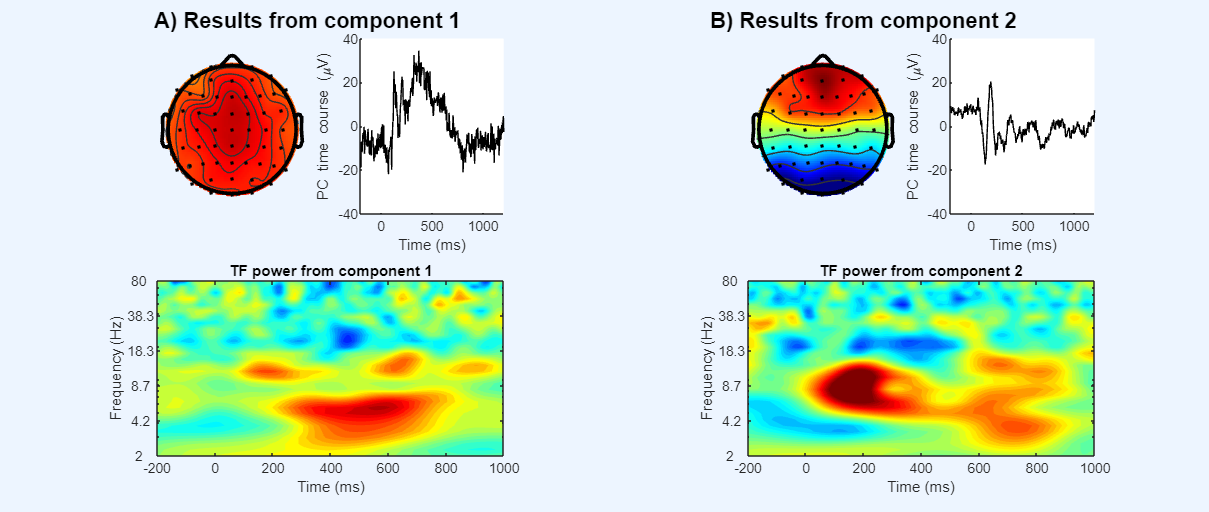

covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

[pc,eigvals] = eig(covar);
pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals);

min_freq =  2;
max_freq = 80;
num_frex = 30;

time = -1:1/EEG.srate:1;
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
s    = logspace(log10(3),log10(10),num_frex)./(2*pi*frex);

n_wavelet            = length(time);
n_data               = EEG.pnts*EEG.trials;
n_convolution        = n_wavelet+n_data-1;
n_conv_pow2          = pow2(nextpow2(n_convolution));
half_of_wavelet_size = (n_wavelet-1)/2;
baseidx              = dsearchn(EEG.times',[-500 -200]');

figure('Position',[100 100 1300 550])

for pcanum=1:2
    pcadata = zeros(EEG.pnts,EEG.trials);
    for i=1:EEG.trials
        pcadata(:,i) = pc(:,pcanum)'*bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    end

    eegfft   = fft(reshape(pcadata,1,EEG.pnts*EEG.trials),n_conv_pow2);
    eegpower = zeros(num_frex,EEG.pnts);

    for fi=1:num_frex
        wavelet = fft( exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(s(fi)^2))) , n_conv_pow2 );
        eegconv = ifft(wavelet.*eegfft);
        eegconv = eegconv(1:n_convolution);
        eegconv = eegconv(half_of_wavelet_size+1:end-half_of_wavelet_size);
        
        temppower = mean(abs(reshape(eegconv,EEG.pnts,EEG.trials)).^2,2);
        eegpower(fi,:) = 10*log10(temppower./mean(temppower(baseidx(1):baseidx(2))));
    end

    offset = (pcanum-1)*3;

    subplot(2,5,1+offset)
    topoplot(double(pc(:,pcanum)),EEG.chanlocs,'plotrad',.53,'maplimits',[-.175 .175]);

    subplot(2,5,2+offset)
    plot(EEG.times,mean(pcadata,2),'k')
    set(gca,'xlim',[-200 1200],'ylim',[-40 40])
    xlabel('Time (ms)')
    ylabel('PC time course (\muV)')
    box off

    subplot(2,5,[6 7]+offset)
    contourf(EEG.times,frex,eegpower,40,'linecolor','none')
    set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(min_freq),log10(max_freq),6),'yticklabel',round(logspace(log10(min_freq),log10(max_freq),6)*10)/10)
    xlabel('Time (ms)')
    ylabel('Frequency (Hz)')
    title([ 'TF power from component ' num2str(pcanum) ])
end

annotation('textbox',[0.12 0.95 0.35 0.05],'String','A) Results from component 1','EdgeColor','none','FontSize',12,'FontWeight','bold')
annotation('textbox',[0.58 0.95 0.35 0.05],'String','B) Results from component 2','EdgeColor','none','FontSize',12,'FontWeight','bold')

**Figure 23.4**

*Activities from the first two PCs. The plots show the topographical map, trial-averaged component time course (this is the ERP of that component), and the time-frequency power.*

The sign of the PCA weights is somewhat arbitrary, meaning that it is possible for the electrode weights to be inverted. Slightly different algorithms (e.g., eigenvalue decomposition vs. singular value decomposition, or the present analyses vs. the Matlab function princomp) may produce identical or nearly identical results but with some components of opposite signs. The Matlab function princomp, for example, forces the largest component to be positive regardless of its original sign. Depending on what you plan on doing with the PCA results, potential flips in sign may not matter. If the sign is important, there are several methods to ensure a nonarbitrary PCA sign, including setting the sign to be positive for the largest component (as the Matlab function princomp does) or setting the sign according to the direction of the data distributions.

## 23.3 Distinguishing Significant from Nonsignificant Components

The number of components in the PCA is equal to the number of variables (electrodes). However, when considering a plot of the percentage variance accounted for over components, you will notice that only the first several components account for "a lot" of variance, and most of the later components account for relatively little variance. Often in the PCA the first several components will be considered signal, whereas the later components will be considered noise. Keep in mind that Local and topographically constrained activity will be reflected in a PC that accounts for relatively little variance in the covariance matrix, although it may be theoretically and empirically significant (thus, it may be signal, not noise). 

Distinguishing significant from nonsignificant components involves determining a percentage variance threshold and considering components that explain variance above that threshold to be significant. There are several ways to determine the threshold: 

- To compute the percentage explained variance that would be expected from each component if all electrodes were uncorrelated with each other. In this case, each component would explain [100 x 1/M] percent of the variance, where M is the number of electrodes/components.

- To use permutation testing, whereby the data are randomly shuffled, a PCA is computed on the shuffled data, and the amount of variance explained in shuffled data, averaged over many repetitions, is taken as the threshold. 

- To examine changes in the slope of the eigenvalue function or visually inspecting the plot of variance accounted for by each PC (this method may be impractical if you are performing PCA over many time segments and frequency bands)

The advantage of permutation-based thresholding over the analytic method described in the previous paragraph is that the data distributions and characteristics are retained. 

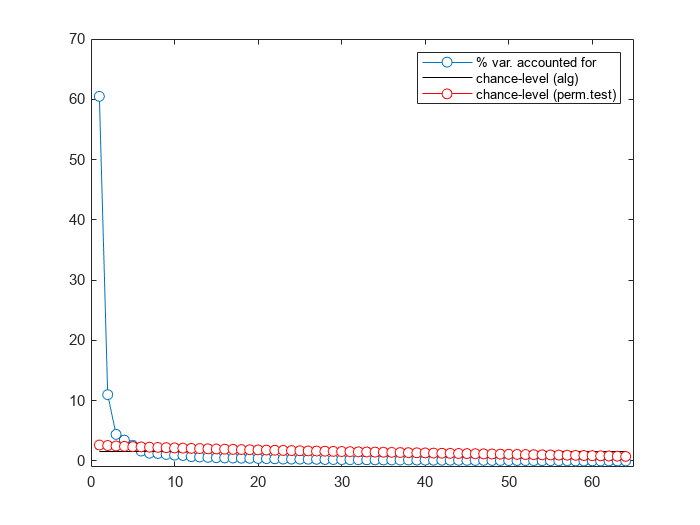

figure

covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;
[pc,eigvals] = eig(covar);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals); % convert to percent change

plot(eigvals,'-o','markerface','w')
set(gca,'ylim',[-1 70],'xlim',[0 65])

hold on
plot([1 EEG.nbchan],repmat(100/EEG.nbchan,1,2),'k')

nperms = 1000;
permeigvals = zeros(nperms,EEG.nbchan);
for permi=1:nperms
    randdat = reshape(erp(randperm(numel(erp))),size(erp));
    covar = (randdat*randdat')./(EEG.pnts-1);
    [pc,eigvals] = eig(covar);
    eigvals = diag(eigvals);
    permeigvals(permi,:) = 100*eigvals(end:-1:1)./sum(eigvals);
end

plot(mean(permeigvals,1),'r-o','markerface','w')

legend({'% var. accounted for';'chance-level (alg)';'chance-level (perm.test)'})

**Figure 23.5**

*Percentage of total variance accounted for by each of 64 components, along with thresholds based either on an analytic solution (the expected amount of variance accounted for assuming that each electrode contributes completely independent information) or on permutation testing (shuffling data points and recomputing the PCA 1000 times). The first component is cut out of the plot to facilitate visual inspection.*

Keep in mind that if you performed independent components analysis and subtracted some components from the data, the rank of the data may be lower than the number of electrodes (this depends on how many components were subtracted and how much variance those components accounted for). The rank of a matrix refers to the number of linearly independent dimensions in the data.

Once the significant components are identified, there are several subsequent analysis options: 

- Treat PCA as a dimensionality reduction technique and analyze only the significant components.

- Treat PCA as a way to denoise the data by projecting back only the significant components.

- Examine how much variance is explained in the data by one or all signal components.

There are several other pieces of information that could be extracted from PCA: 

- Compute the variance accounted for by all components with below-threshold eigenvalues to estimate the "noise" of the global EEG response (this measure will likely be correlated but not redundant with the amount of variance explained by the first component). 

- There are PCA-based measures of the complexity of a system.  This can be quantified as the ratio of the first to the second eigenvalue (or the first to the average of all other suprathreshold eigenvalues) or as the exponential steepness of the decrease in eigenvalues. 

- Quantify the "PCA coherence," defined as the ratio of the squared first eigenvalue to the sum of squared eigenvalues (this is also correlated with the percentage variance of the first component).

## 23.4 Rotating PCA Solutions

PCA as presented so far forces all components to be orthogonal to each other. This might be too strong an assumption; it is reasonable to expect that topographical patterns of covariance are intercorrelated.

Components can be "rotated" to allow them to be correlated (i.e., oblique) or to allow them to capture additional variance (that is, components might not necessarily optimally capture variance due to the orthogonality constraint). Rotation involves selecting a number of significant components and applying iterative algorithms to further minimize variance along the selected dimensions. There are several methods for rotating principal components that make different assumptions about whether and how components can be correlated. Note that a rotated PCA solution will change if you rotate a different number of components, whereas the unrotated solution will always be the same.

Whether you should rotate the PCA solution depends largely on the reason for performing the PCA. If you want to isolate overlapping ERP components, for example, rotation will facilitate a cleaner interpretation of the components.

## 23.5 Time-Resolved PCA

So far, the covariance matrix used to compute the PCA was made from all time points. It may seem inappropriate to include all time points into the covariance matrix, particularly the buffer zones (for edge artifacts) or intertrial intervals. Furthermore, different time periods within the trial might be associated with different neuroelectrical modes or covariance configurations. Thus, PCA can be performed over successive time windows.

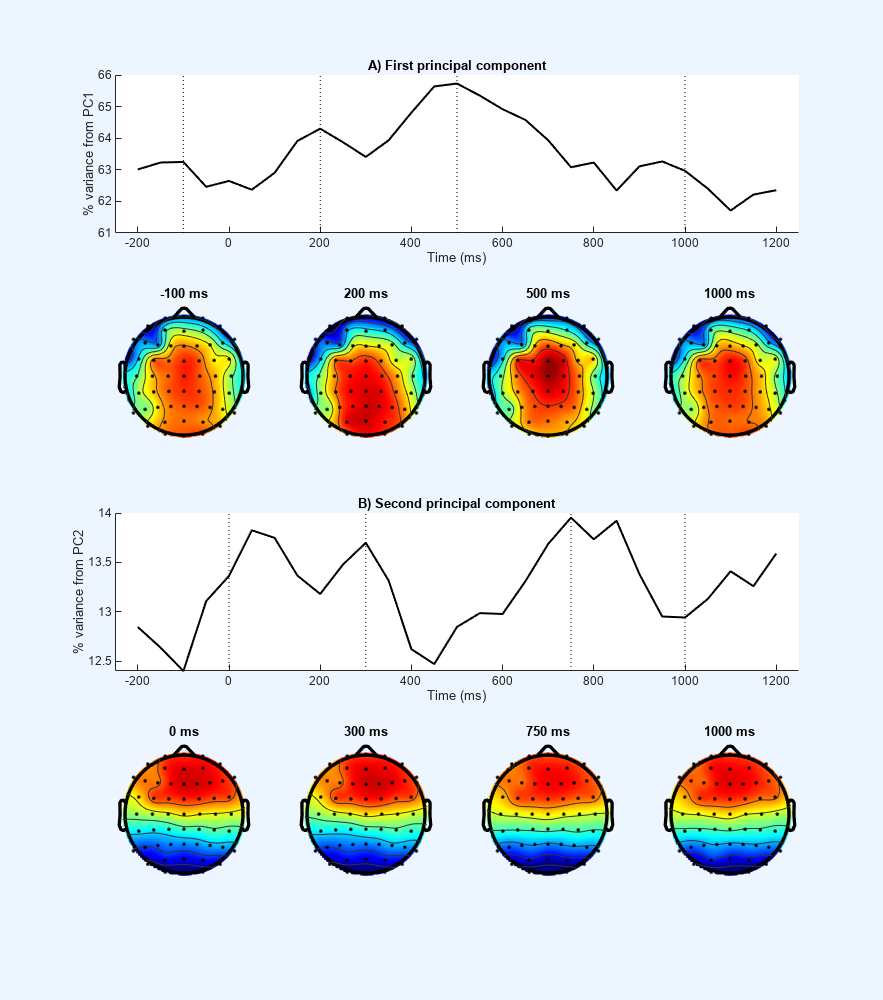

centertimes = -200:50:1200;
timewindow  = 200;
timesidx    = dsearchn(EEG.times',centertimes');
timewinidx  = round(timewindow/(1000/EEG.srate));

figure('Position',[100 100 750 850])

for whichcomp=1:2
    if whichcomp==1
        maptimes = [ -100 200 500 1000 ];
        clim     = [.08 .15];
         panelstr = 'A) First principal component';
    else
        maptimes = [ 0 300 750 1000 ];
        clim     = [-.2 .2];
        panelstr = 'B) Second principal component';
    end

    pcvariance = zeros(size(centertimes));
    firstpcas  = zeros(length(centertimes),EEG.nbchan);
    mapsidx    = dsearchn(centertimes',maptimes');

    for ti=1:length(centertimes)
        covar = zeros(EEG.nbchan);
        for i=1:EEG.trials
            eeg = squeeze(EEG.data(:,timesidx(ti)-timewinidx:timesidx(ti)+timewinidx,i));
            eeg = bsxfun(@minus,eeg,mean(eeg,2));
            covar = covar + (eeg*eeg')./(EEG.pnts-1);
        end
        covar = covar./i;

        [pc,eigvals] = eig(covar);
        pc      = pc(:,end:-1:1);
        eigvals = diag(eigvals);
        eigvals = 100*eigvals(end:-1:1)./sum(eigvals);

        pcvariance(ti)  = eigvals(whichcomp);
        firstpcas(ti,:) = pc(:,whichcomp);
    end

    offset = (whichcomp-1)*8;

    subplot(4,4,(1:4)+offset)
    plot(centertimes,pcvariance,'k','LineWidth',1.2)
    hold on
    yl = get(gca,'ylim');
    plot([maptimes; maptimes],repmat(yl',1,length(maptimes)),'k:')
    set(gca,'xlim',[-250 1250],'ylim',yl)
    xlabel('Time (ms)')
    ylabel([ '% variance from PC' num2str(whichcomp) ])
    title(panelstr)
    box off

    for i=1:length(maptimes)
        subplot(4,4,4+i+offset)
        topoplot(firstpcas(mapsidx(i),:),EEG.chanlocs,'plotrad',.53,'maplimits',clim);
        title([ num2str(maptimes(i)) ' ms' ]);
    end
end

**Figure 23.6**

*Results of PCA performed over time. *

If you perform a time-resolved PCA, you will need to decide how much time to include when computing the covariance matrix. There is a trade-off between: 

- Temporal specificity (shorter periods of time help isolate temporal dynamics, particularly temporally brief dynamics). 

- Signal-to-noise ratio (longer periods of time produce more stable estimates of covariance). 

If you perform time-resolved PCA on frequency-band-specific activity, the width of the temporal window also depends on the center frequency. In most cases, a time window of around 400 ms should be sufficient. Time windows less than 100 ms should be avoided unless you have a specific justification. For resting-state data, you might improve the signal-to-noise ratio by segmenting the data into nonoverlapping windows of 1-2 s.

## 23.6 PCA with Time-Frequency Information

PCA can be combined with temporal bandpass filtering to highlight frequency-band-specific spatial features. This can be done by first bandpass filtering the time-domain signal and then following the same procedures as already outlined in this chapter.

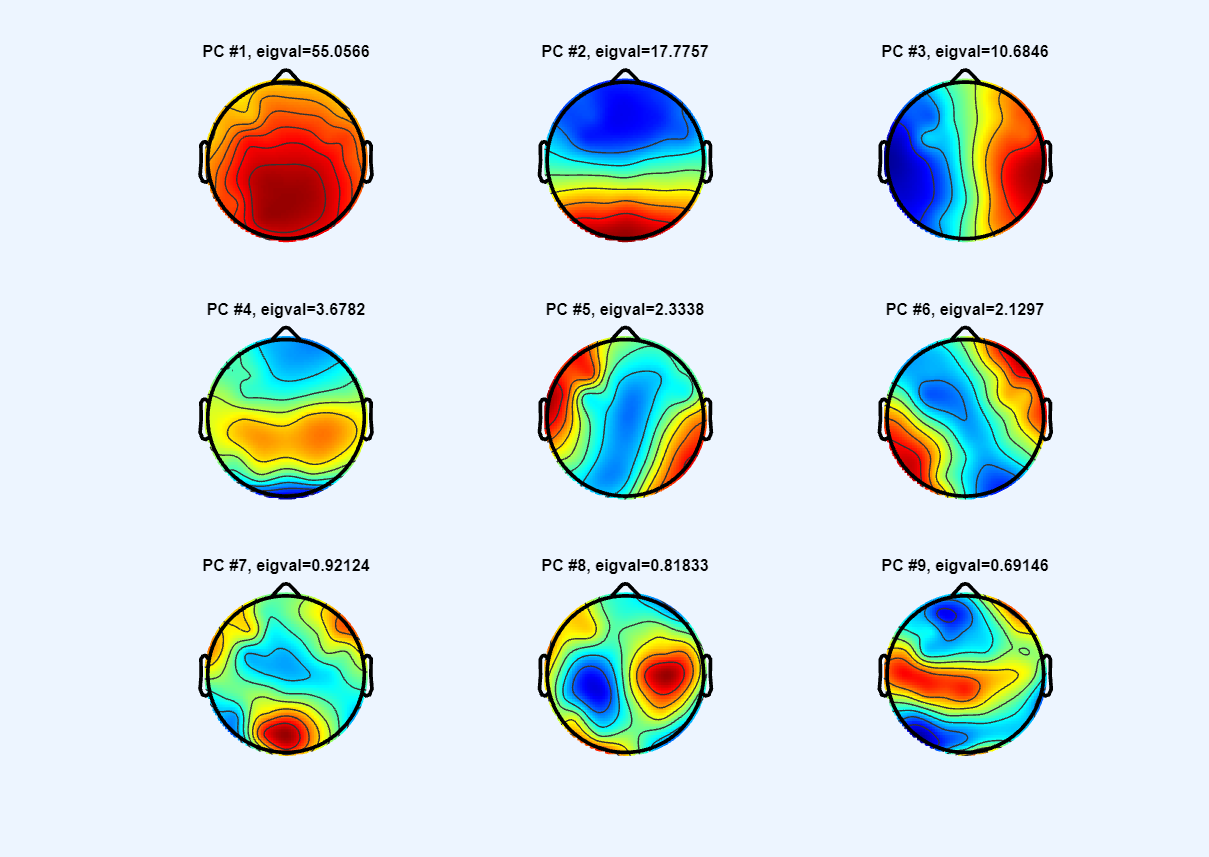

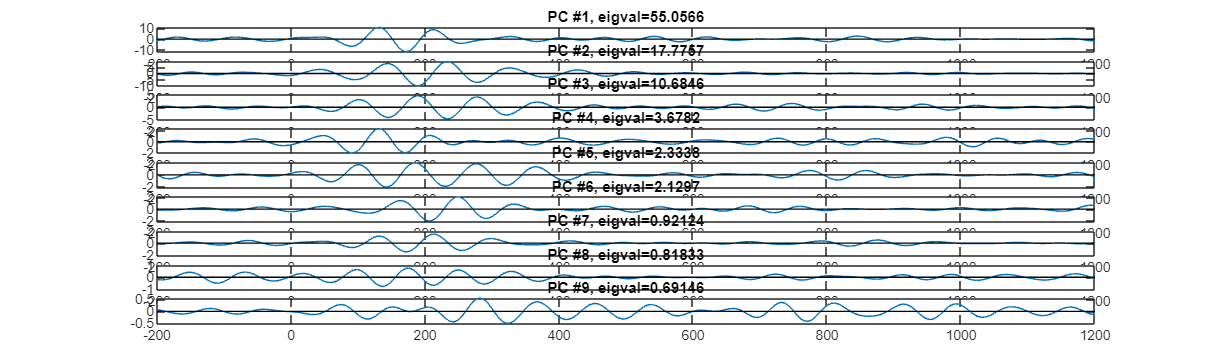

center_freq = 12;
filter_frequency_spread  = 3;
transition_width  = 0.2;

nyquist       = EEG.srate/2;
filter_order  = round(3*(EEG.srate/(center_freq-filter_frequency_spread)));

ffrequencies  = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread) (center_freq-filter_frequency_spread) (center_freq+filter_frequency_spread) (1+transition_width)*(center_freq+filter_frequency_spread) nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(filter_order,ffrequencies,idealresponse);

filter_result = filtfilt(filterweights,1,double(reshape(EEG.data,EEG.nbchan,EEG.pnts*EEG.trials))')';
filter_result = reshape(filter_result,EEG.nbchan,EEG.pnts,EEG.trials);

covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = squeeze(filter_result(:,:,i)) - repmat(squeeze(mean(filter_result(:,:,i),2)),1,EEG.pnts);
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

[pc,eigvals] = eig(covar);

pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals);

for i=1:9
    figure(10)
    subplot(3,3,i)
    topoplot(pc(:,i),EEG.chanlocs,'electrodes','off','plotrad',.53);
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])

    figure(11)
    subplot(9,1,i)
    plot(EEG.times,pc(:,i)'*squeeze(mean(filter_result,3)))
    hold on
    plot(get(gca,'xlim'),[0 0],'k')
    set(gca,'xlim',[-200 1200])
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])
end

**Figure 23.7**

*Same as figure 23.3B but for data filtered around 12 Hz.*

The time courses in figure 23.7 were generated by multiplying the PCA weights by the 12-Hz-filtered data. In theory, it is also possible to apply the 12-Hz-defined PCA weights to broadband data or to data filtered at a different frequency, but these time courses may be more difficult to interpret because the PCA weights are being applied to data other than what they were computed from.

## 23.7 PCA across Conditions

PCA can be used for testing condition differences in part because PCA can be used as a data reduction technique. Rather than comparing the electrode-level activity across conditions, you can compare the PC-defined activity across conditions. For condition data, you can compute the PCA based on either the covariance from all conditions  or the covariance from each condition separately. Advantages of computing the covariance based on all trials from all conditions include that:

- The signal-to-noise ratio of the covariance is maximized because many trials contribute to the covariance matrix.

- It facilitates interpreting condition differences, because those differences cannot be due to topographical differences in PC weights. 

The main advantage of computing the covariance matrices separately for each condition is that the PCA results will have increased sensitivity to identifying condition differences because the weights are tuned to the properties of each condition.

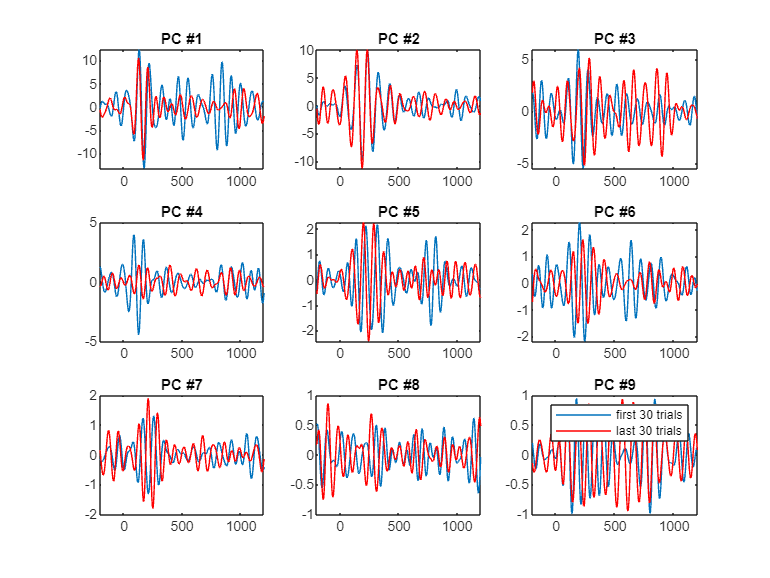

figure

covar = zeros(EEG.nbchan);
for i=1:30
    eeg = squeeze(filter_result(:,:,i)) - repmat(squeeze(mean(filter_result(:,:,i),2)),1,EEG.pnts);
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

[pc,~] = eig(covar);
pc = pc(:,end:-1:1);

for i=1:9
    subplot(3,3,i)
    plot(EEG.times,pc(:,i)'*squeeze(mean(filter_result(:,:,1:30),3)))
    hold on
    set(gca,'xlim',[-200 1200])
    title([ 'PC #' num2str(i) ])
end


covar = zeros(EEG.nbchan);
for i=EEG.trials-29:EEG.trials
    eeg = squeeze(filter_result(:,:,i)) - repmat(squeeze(mean(filter_result(:,:,i),2)),1,EEG.pnts);
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./30;

[pc,eigvals] = eig(covar);
pc = pc(:,end:-1:1);

for i=1:9
    subplot(3,3,i)
    plot(EEG.times,pc(:,i)'*squeeze(mean(filter_result(:,:,end-30:end),3)),'r')
    set(gca,'xlim',[-200 1200])
    title([ 'PC #' num2str(i) ])
end
legend({'first 30 trials';'last 30 trials'})

**Figure 23.8**

the PCA is computed separately on the first and last 30 trials* (from the 12-Hz-filtered data shown in figure 23.7), and then the PCA weights were applied separately to the first 30 and the last 30 trials.*

## 23.8 Independent Components Analysis

Some aspects of independent components analysis (ICA) are conceptually or mathematically similar to PCA. Here is the key difference: 

- PCA is used to decorrelate and reduce the dimensionality of a multivariate signal; ICA is used to demix independent sources that are embedded in multivariate signals. Thus, PCA decorrelates and ICA demixes.

- PCA is computed using only second-order statistics (variances), whereas ICA also uses higher-order statistics such as skew and kurtosis. 

- ICA uses iterative methods based on minimizing cost functions (typically via mutual information) to adjust weights, whereas PCA does not iterate to adjust weights except during some rotation methods. 

- PCA components are constrained to be orthogonal to each other (except in some methods of rotation), whereas ICA does not assume that sources are orthogonal to each other.

ICA is a standard and widely used technique in EEG data analyses. It is used to clean data prior to analyses, and it is also used directly in analyses by analyzing component time courses instead of electrode time courses.

## 23.9 Describing This Method in Your Methods Section

Because PCA can be used for many different purposes, it is important to state clearly the purpose of performing the components analysis. This will help readers interpret the results, and it will also help them evaluate the appropriateness of the analysis. Some PCA choices may be appropriate or inappropriate, depending on why you are performing the PCA (factor rotation is one example). Be clear about what data were used to compute the covariance matrices, whether filtering was applied, and what time windows were used. If you used software packages to perform the analyses, note which one was used and whether you changed any parameters from the default settings.